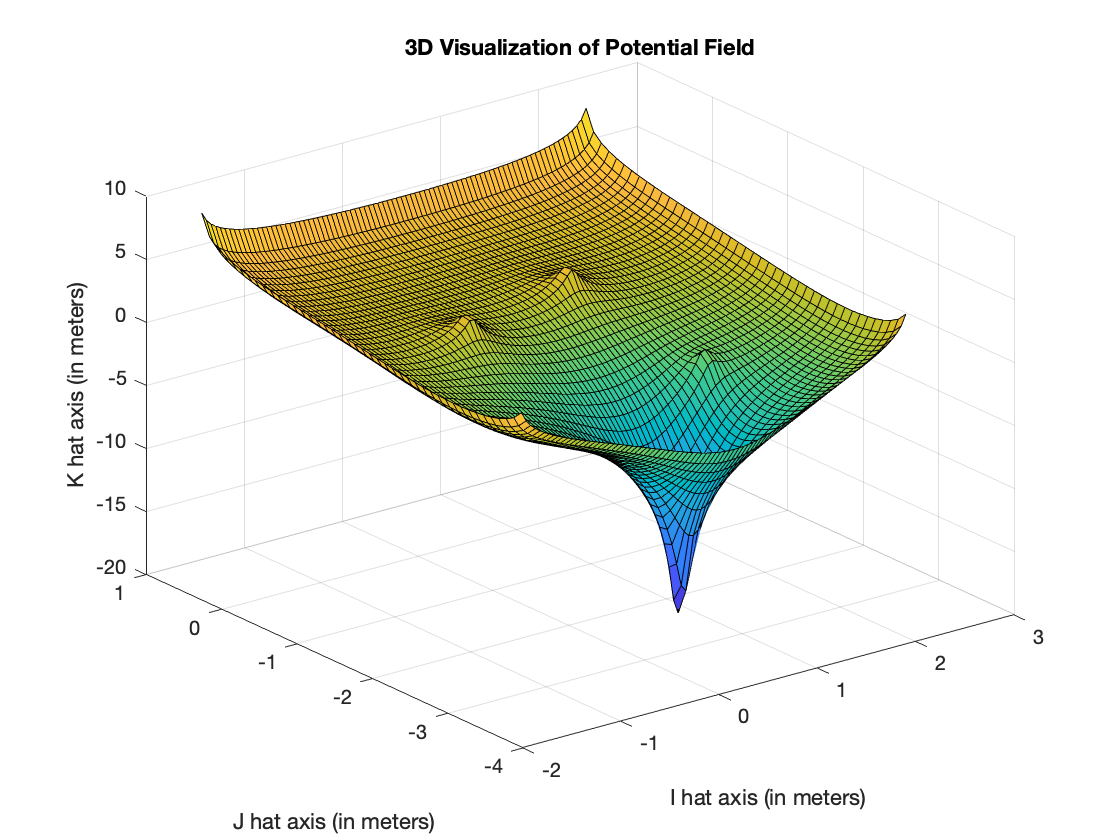

%Create the meshgrid
[x,y] = meshgrid(-1.5:(sqrt(2)/30):2.5, -3.37:(sqrt(2)/14):1);

%Create sinks for the walls
Wall_1 = log(sqrt((y-1).^2));
Wall_2 = log(sqrt((y+3.37).^2));
wall_3 = log(sqrt((x+1.5).^2));
wall_4 = log(sqrt((x-2.5).^2));

%Create sinks for the squares
Square_1 = log(sqrt((x+.25).^2+(y+1).^2));
Square_2 = log(sqrt((x-1).^2+(y+0.7).^2));
Square_3 = log(sqrt((x-1.4).^2+(y+2).^2));

%Create Barrel but also scale it by a factor of 5
BoB = 5*log(sqrt((x-0.75).^2+(y+2.5).^2));

%Add the equations together
V = -(Wall_1+Wall_2+wall_3+wall_4+Square_1+Square_2+Square_3-BoB);

%Visualize the plot (Surface and contour)
figure()
surf(x,y,V)
title("3D Visualization of Potential Field")
xlabel("I hat axis (in meters)")
ylabel("J hat axis (in meters)")
zlabel("K hat axis (in meters)")

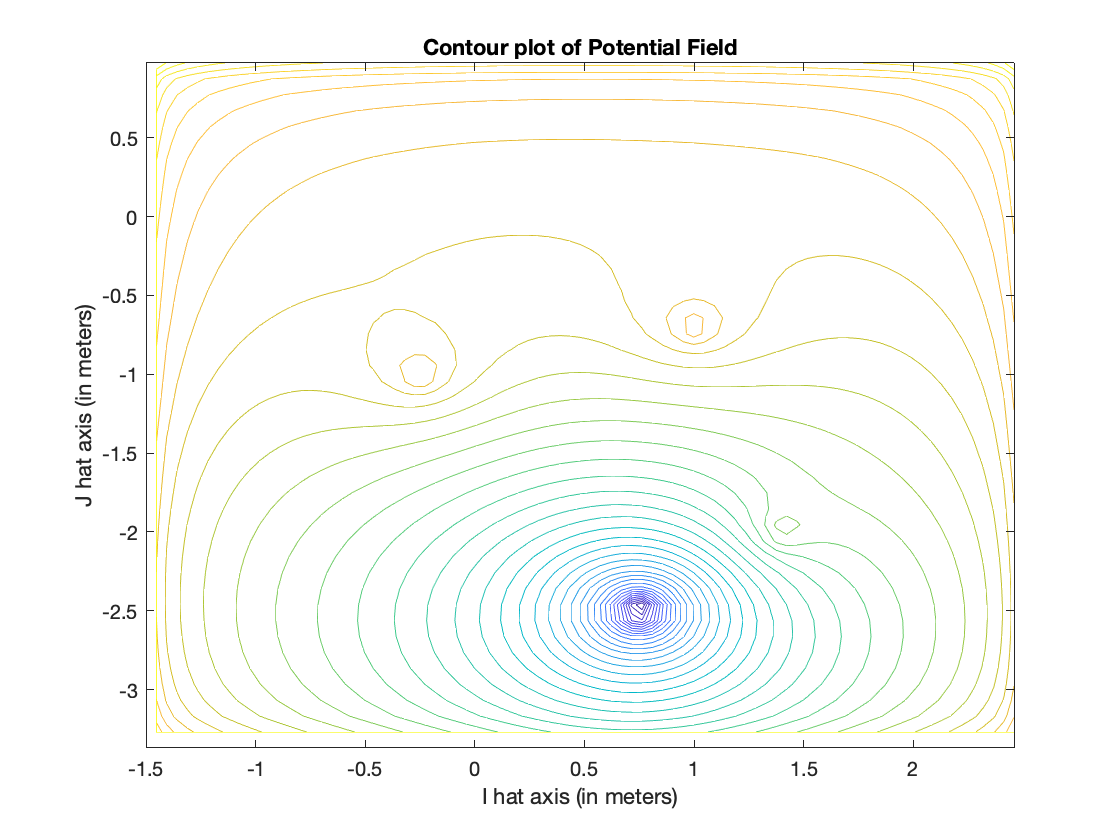



figure()
contour(x,y,V,40)
title("Contour plot of Potential Field")
xlabel("I hat axis (in meters)")
ylabel("J hat axis (in meters)")

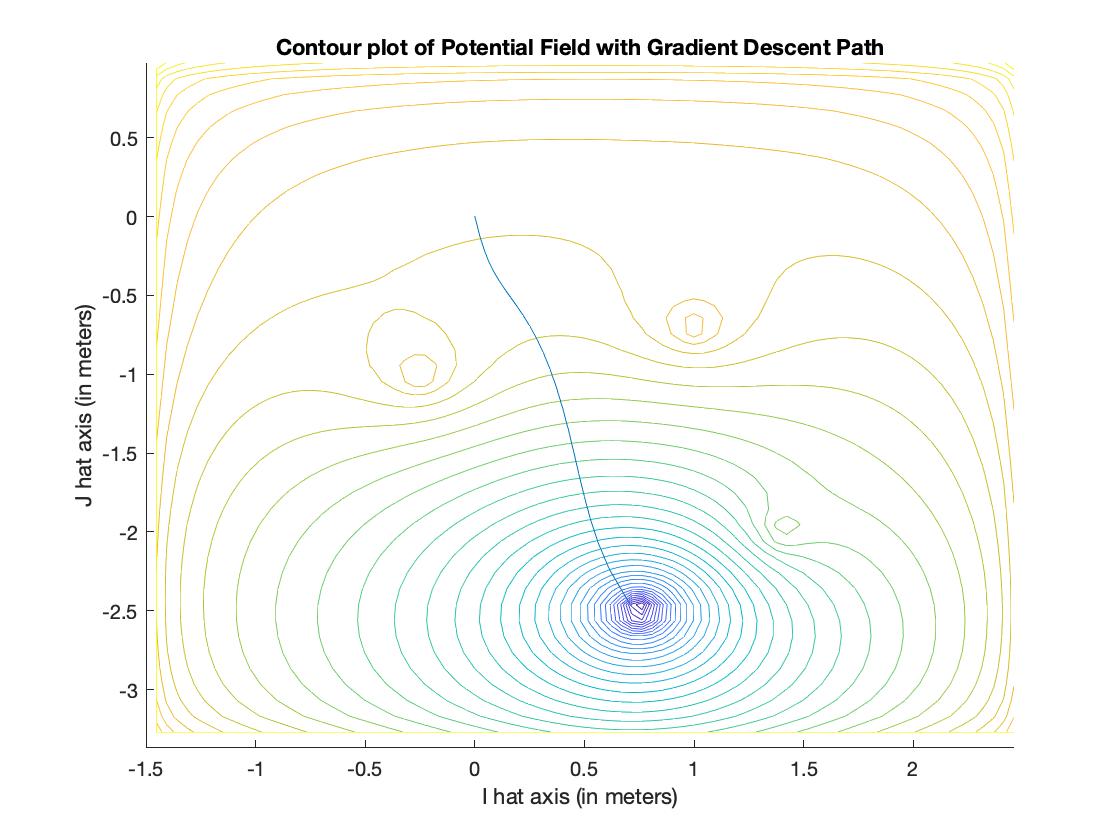



figure()
hold on
contour(x,y,V,40)
title("Contour plot of Potential Field with Gradient Descent Path")
xlabel("I hat axis (in meters)")
ylabel("J hat axis (in meters)")

%Put gradient descent on to contour 
load Dscent_position.mat
plot(position(:,1),position(:,2))
hold off

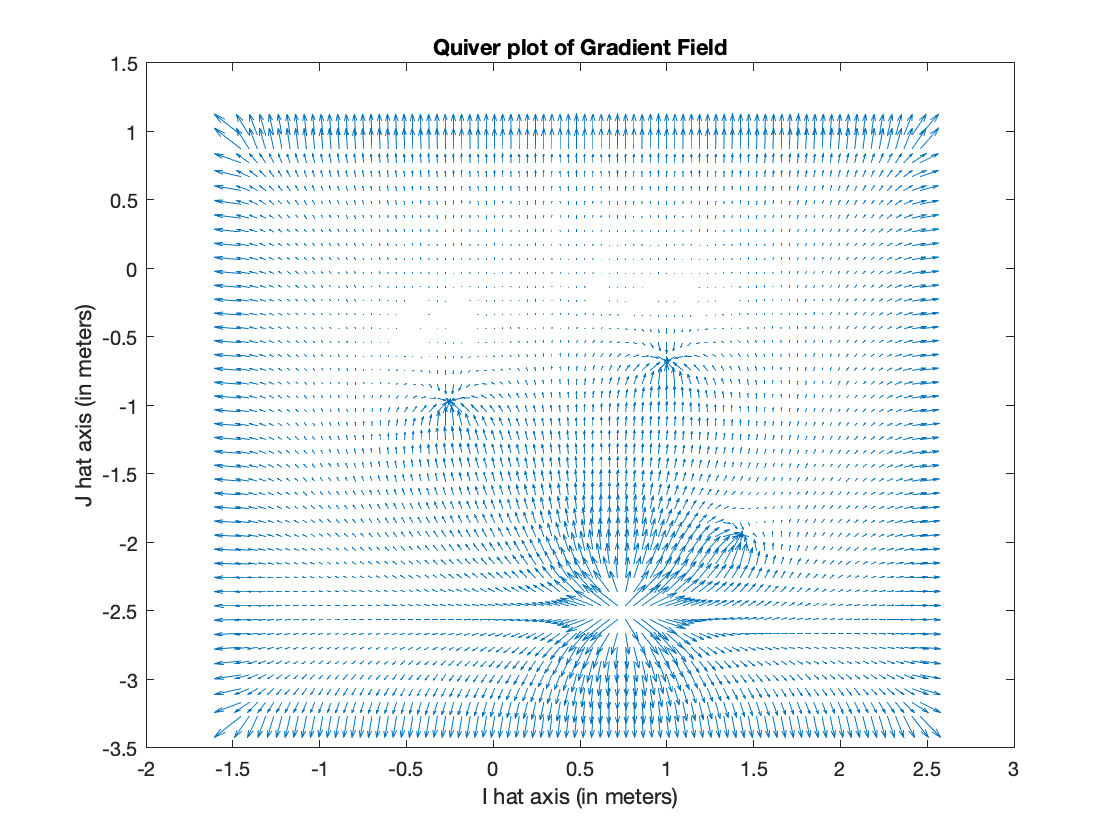


%Develop the gradient from the equation remove points that head towards
%infinity
[gradx, grady] = gradient(V, 0.11);
gradx(gradx > 1e+1) = 1e+1; gradx(gradx < -1e+1) = -1e+1; 
grady(grady > 1e+1) = 1e+1; grady(grady < -1e+1) = -1e+1; 

%Visualize gradient
figure()
quiver(x,y,gradx,grady,2)
title("Quiver plot of Gradient Field")
xlabel("I hat axis (in meters)")
ylabel("J hat axis (in meters)")

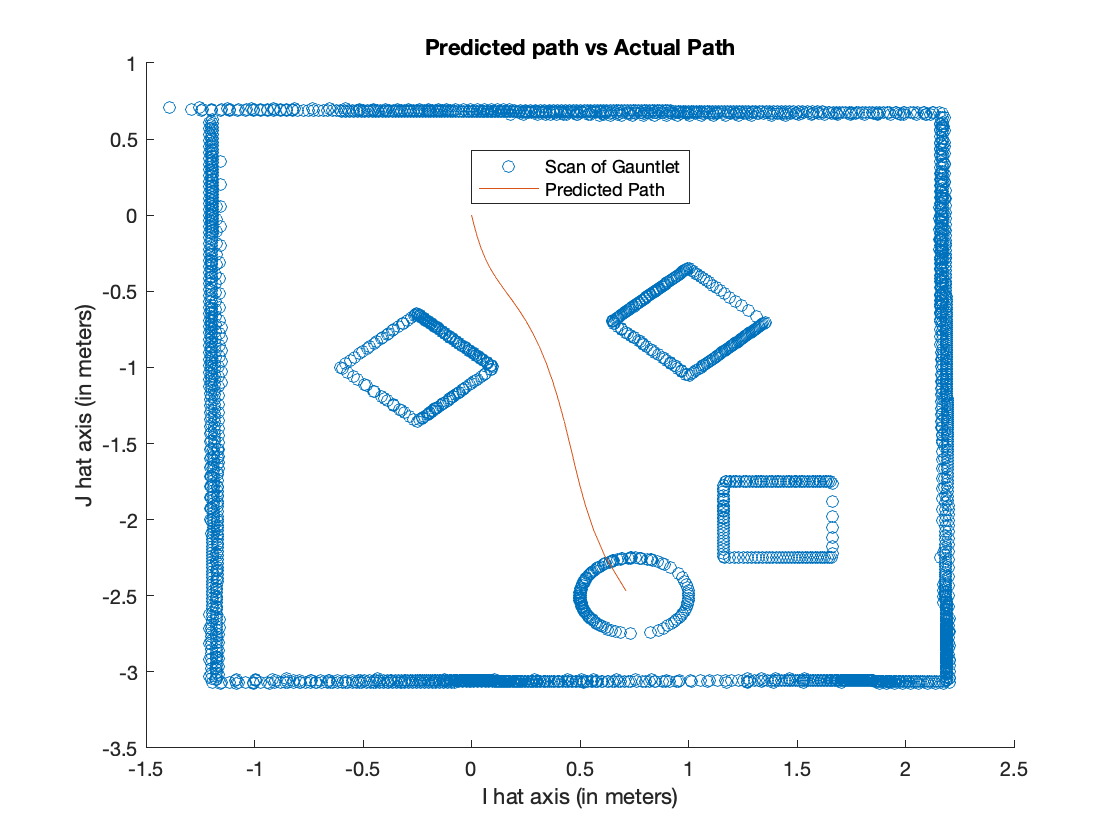

%Symbolically recreate the equation
syms x y 

Wall_1 = log(sqrt((y-1).^2));
Wall_2 = log(sqrt((y+3.37).^2));
wall_3 = log(sqrt((x+1.5).^2));
wall_4 = log(sqrt((x-2.5).^2));

Square_1 = log(sqrt((x+.25).^2+(y+1).^2));
Square_2 = log(sqrt((x-1).^2+(y+0.7).^2));
Square_3 = log(sqrt((x-1.4).^2+(y+2).^2));
 
BoB = 5*log(sqrt((x-0.75).^2+(y+2.5).^2));
V1 = -(Wall_1+Wall_2+wall_3+wall_4+Square_1+Square_2+Square_3-BoB);

%Convert the symbolic into a function handel 
g = matlabFunction(gradient(V1));

%Perform gradient ascent
position = gradient_descent(g,[0 0],0.9,0.15,30,200);

%Create the plot of the gauntlet
load Cartesians.mat
[i,j] = meshgrid(-1.5:(sqrt(2)/14):2.5, -3.37:(sqrt(2)/14):1);
points = sortrows(transpose(all_points));


%Visualize the gradient ascent on the plot
figure()
hold on
scatter(points(:,1),points(:,2))
plot(position(:,1),position(:,2))
title("Predicted path vs Actual Path")
xlabel("I hat axis (in meters)")
ylabel("J hat axis (in meters)")

legend("Scan of Gauntlet","Predicted Path","Location","best")


%Export the equation to be used in simulation
save('Equation.mat','V1')
save('Dscent_position.mat','position')


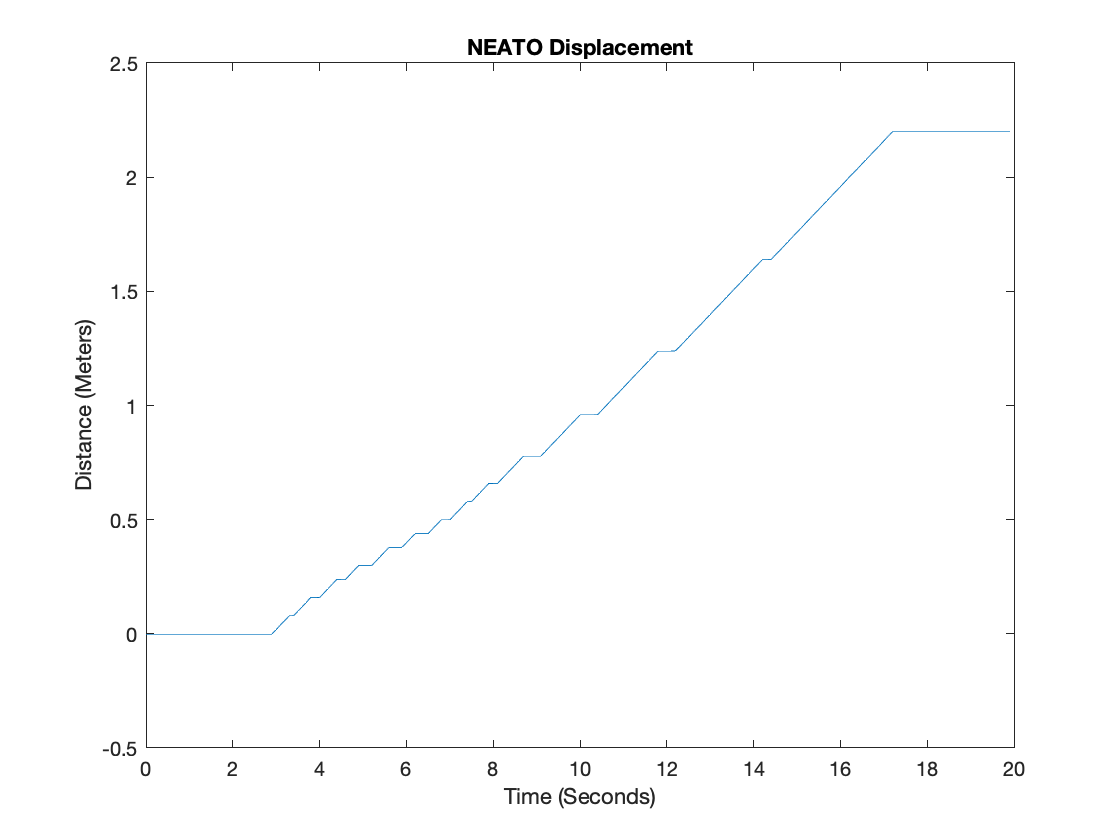

%Load encoder data from simulation
d=0.235;
encoders = readtable("my_data.csv");
start_index = 50;
end_index = 249;
time = encoders.time(start_index:end_index)-encoders.time(start_index);
left_x = encoders.encoderLeft(start_index:end_index);
right_x = encoders.encoderRight(start_index:end_index);
distance = (left_x + right_x)./2;
figure();
plot(time,distance)
title("NEATO Displacement")
xlabel("Time (Seconds)"); ylabel("Distance (Meters)")


calc_r = zeros(length(time),2);
theta = zeros(length(time),1);
dt = diff(time);


encoder_scale = 1.15

encoder_scale = 1.1500

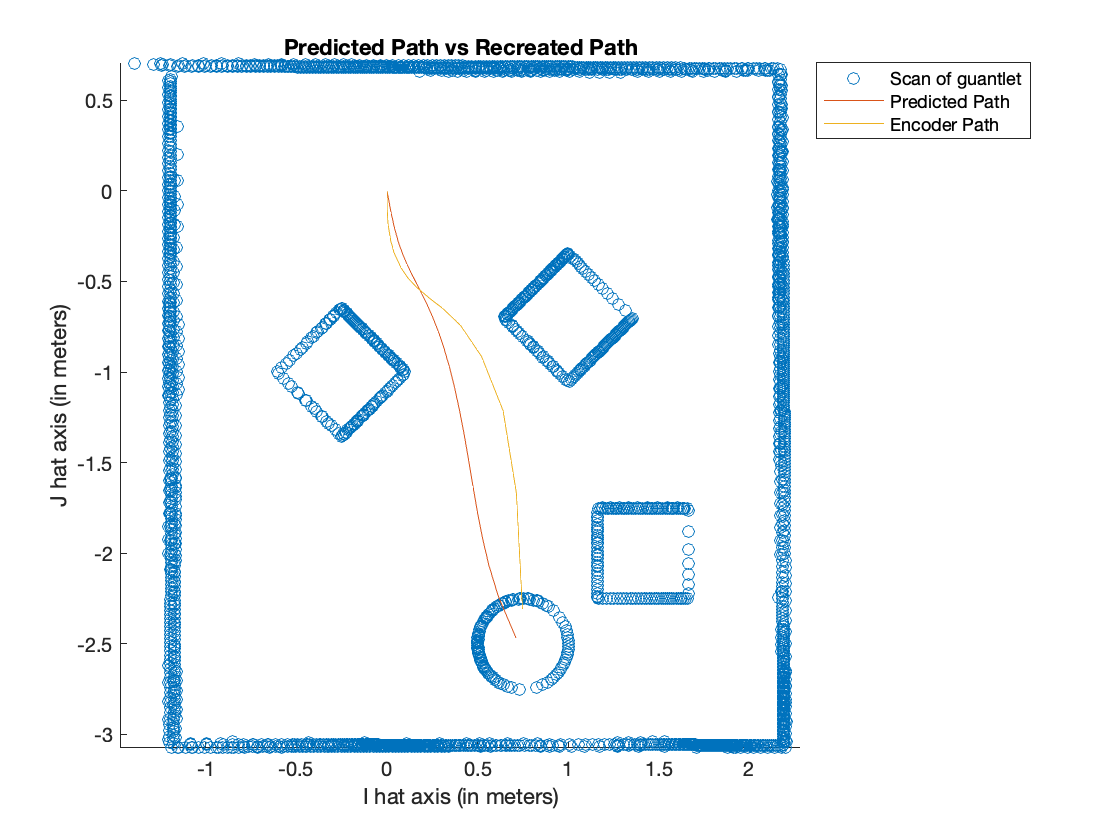

%scale the encoders because they seem to be off by a scale factor
v_l = diff(left_x)./dt*encoder_scale;
v_r = diff(right_x)./dt*encoder_scale;
v = (v_l + v_r)/2;
omega = (v_l - v_r)./dt; 
%Borrow the first positions from the theoretical positions
start_heading = [1;0]; %taken from the Run_SIM.m file
theta(1,:) = atan(start_heading(2)/start_heading(1));
calc_r(1,:) = [0; 0];

for x = 1:length(dt)
    calc_r(x+1,1) = calc_r(x,1) + v(x)*cos(theta(x))*dt(x); %x position
    calc_r(x+1,2) = calc_r(x,2) - v(x)*sin(theta(x))*dt(x); %y position
    theta(x+1) = theta(x) + omega(x)*dt(x);
    %for plotting the theoretical vectors later
end

%Visualize predicted vs actual path
figure()
hold on
scatter(points(:,1),points(:,2))
title("Predicted Path vs Recreated Path")
xlabel("I hat axis (in meters)")
ylabel("J hat axis (in meters)")
plot(position(:,1),position(:,2))
plot(calc_r(:,1),calc_r(:,2));
legend("Scan of guantlet","Predicted Path","Encoder Path","Location","northeastoutside")
axis equal;


C = ismember(position,calc_r);